c = 1;
m = 2;
k = 10;
Fs = 100;
ts = 1 / Fs;
duration = 5; % [seconds]
nSamples = duration / ts;
time = (0 : nSamples) * ts;
u = time(time == 1);

A = [0 1;
    -k/m -c/m];

B = [0; 1/m];

C = [1 0];

D = 1;

[v, l] = eig(A)

v =   -0.0456 - 0.4057i  -0.0456 + 0.4057i
   0.9129 + 0.0000i   0.9129 + 0.0000i


l =   -0.2500 + 2.2220i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2500 - 2.2220i


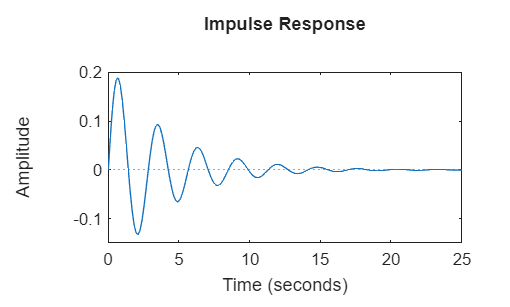


sys = ss(A, B, C, D);

impulse(sys)


Ahat = [1.3 42; 1125 0.2] * A;

[vh, lh] = eig(A);